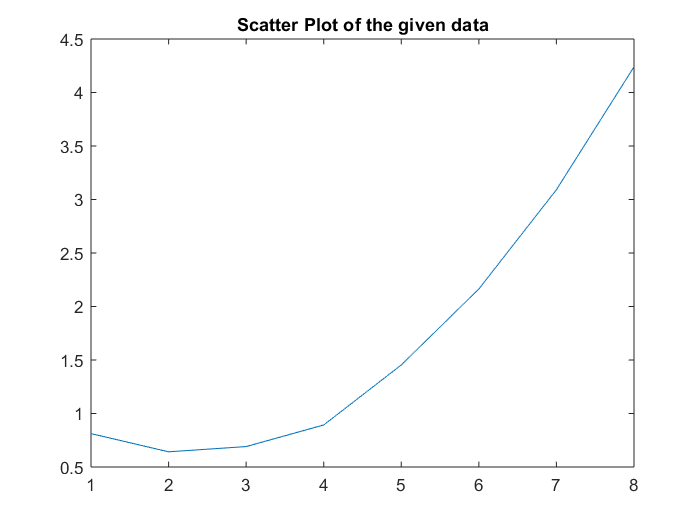

 format long 
 
 % initialize variables for all the functions
 syms f(t) x_l
 
 % import data
 data = importdata('FP_data_Q8.txt');
 x = data(:,1);
 y = data(:,2);
 
 % plot the given data
 plot(x,y)
 title('Scatter Plot of the given data')
 hold off

lenData = length(data);
A1 = ones(lenData, 3);
B1 = zeros(lenData, 1);

% create the desired matrices 
for i=1:lenData
    A1(i,2) = x(i);
    A1(i,3) = x(i)^2;
    B1(i) = y(i);
end

% find the normal matrices on each side of the eqn
A_T1 = transpose(A1);
sqr1 = A_T1*A1;
ATB1 = A_T1*B1;
% calculate the upper and lower triangle using cholosky
L1 = chol(sqr1, 'lower');
L_T1 = chol(sqr1, 'upper');

z1 = inv(L1)*ATB1;
x1 = inv(L_T1)*z1;
x1 = x1

x1 =    1.218357142857155
  -0.516250000000007
   0.111892857142858


% compare with the using the equation
x1 = inv(sqr1)*ATB1

x1 =    1.218357142857143
  -0.516249999999996
   0.111892857142858


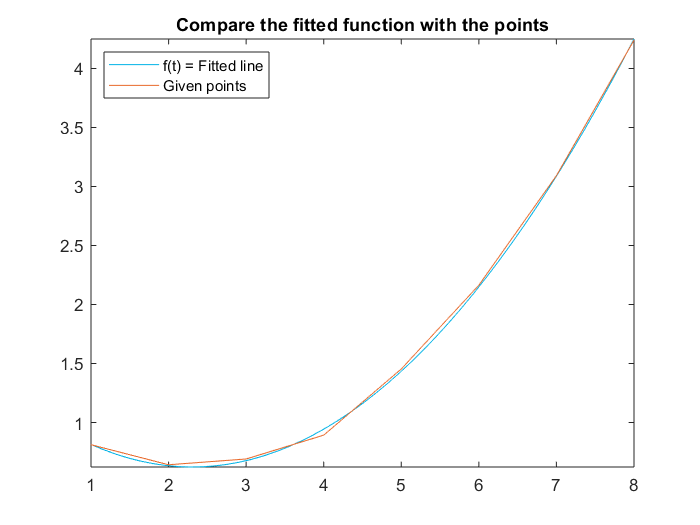

% show the final function
f(t) = x1(1) + x1(2)*t + x1(3)*t^2;
% function plotted against the points
 fplot(f(t), [1,8], 'Color',[0,0.7,0.9])
 hold on
 plot(x,y,'Color',[0.9100,0.4100,0.1700])
 legend({'f(t) = Fitted line', 'Given points'},'Location','Northwest')
 title('Compare the fitted function with the points')
 hold off

 % find the point where there is the highest absolute error
 max_abs_error = 0;
 max_index = 0;
 
 % keep the index with the highest abs error
 for i=1:length(x)
     abs_error = abs(f(x(i)) - y(i));
     if abs_error >  max_abs_error
         max_index = i;
         max_abs_error = abs_error;
     end
 end
 max_index

max_index =      4


 max_abs_error = double(max_abs_error)

max_abs_error =    0.050642857142857


 x(max_index) = [];
 y(max_index) = [];
 
% take the index with the high abs and interpolate it with Lagrange 
f_l = LagrangePolynomial(x_l, x, y)

$$L\_coeffs = \left(\begin{array}{c} \frac{\left(x_{l}-2\right)\,\left(x_{l}-3\right)\,\left(x_{l}-5\right)\,\left(x_{l}-6\right)\,\left(x_{l}-7\right)\,\left(x_{l}-8\right)}{1680}\\ -\frac{\left(x_{l}-1\right)\,\left(x_{l}-3\right)\,\left(x_{l}-5\right)\,\left(x_{l}-6\right)\,\left(x_{l}-7\right)\,\left(x_{l}-8\right)}{360}\\ \frac{\left(\frac{x_{l}}{2}-\frac{1}{2}\right)\,\left(x_{l}-2\right)\,\left(x_{l}-5\right)\,\left(x_{l}-6\right)\,\left(x_{l}-7\right)\,\left(x_{l}-8\right)}{120}\\ -\frac{\left(\frac{x_{l}}{4}-\frac{1}{4}\right)\,\left(x_{l}-2\right)\,\left(x_{l}-3\right)\,\left(x_{l}-6\right)\,\left(x_{l}-7\right)\,\left(x_{l}-8\right)}{36}\\ \frac{\left(\frac{x_{l}}{5}-\frac{1}{5}\right)\,\left(x_{l}-2\right)\,\left(x_{l}-3\right)\,\left(x_{l}-5\right)\,\left(x_{l}-7\right)\,\left(x_{l}-8\right)}{24}\\ -\frac{\left(\frac{x_{l}}{6}-\frac{1}{6}\right)\,\left(x_{l}-2\right)\,\left(x_{l}-3\right)\,\left(x_{l}-5\right)\,\left(x_{l}-6\right)\,\left(x_{l}-8\right)}{40}\\ \frac{\left(\frac{x_{l}}{7}-\frac{1}{7}\right)\,\left(x_{l}-2\right)\,\left(x_{l}-3\right)\,\left(x_{l}-5\right)\,\left(x_{l}-6\right)\,\left(x_{l}-7\right)}{180} \end{array}\right)$$

$$f\_l = -\frac{{x_{l}}^{6}}{336000}+\frac{169\,{x_{l}}^{5}}{1680000}-\frac{729\,{x_{l}}^{4}}{560000}+\frac{13547\,{x_{l}}^{3}}{1680000}+\frac{4489\,{x_{l}}^{2}}{52500}-\frac{65291\,x_{l}}{140000}+\frac{593}{500}$$

% interpolate the point of max error
ypt_new = double(subs(f_l,x_l,max_index))

ypt_new =    0.962257142857143


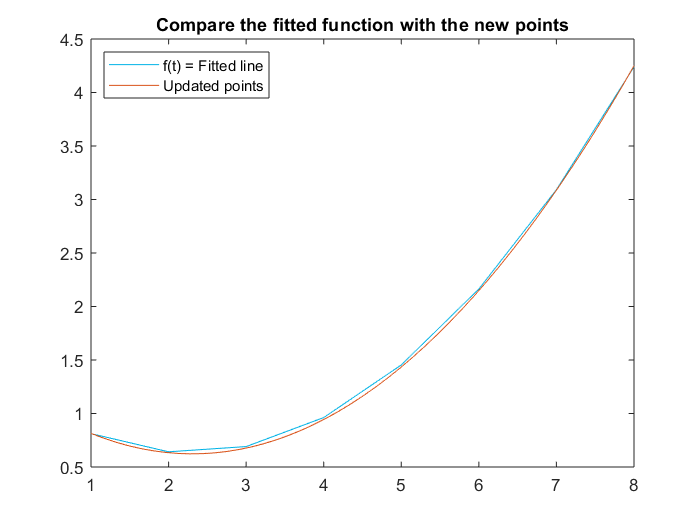

% put the new point back into the points 
x_new = [x(1:max_index-1); max_index; x(max_index:end)];
y_new = [y(1:max_index-1); ypt_new; y(max_index:end)];

% plot the new functions vs the orinal poly fit
plot(x_new,y_new,'Color',[0,0.7,0.9])
hold on
fplot(f(t),[1,8])
legend({'f(t) = Fitted line', 'Updated points'},'Location','Northwest')
title('Compare the fitted function with the new points')
hold off